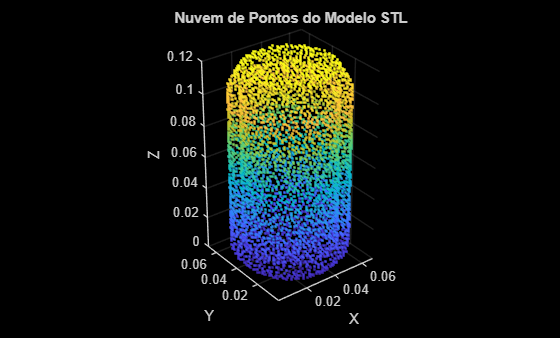

% Leitura do STL
meshData = stlread("C:\Users\pecci\OneDrive\Desktop\Modelos_garra\canYellow.stl");
%meshData = stlread("C:\Users\pecci\OneDrive\Desktop\Modelos_garra\bottle.stl");
% Detectar o tipo de retorno
if isa(meshData, "triangulation")
    % Já está no formato correto
    tri = meshData;
    
elseif isstruct(meshData) && all(isfield(meshData, ["Points", "ConnectivityList"]))
    % Estrutura retornada por stlread moderno
    tri = triangulation(meshData.ConnectivityList, meshData.Points);
    
elseif iscell(meshData)
    % Se for uma célula: [faces, vertices] = stlread(...)
    [faces, vertices] = meshData{:};
    tri = triangulation(faces, vertices);
    
else
    error("Formato de saída de stlread não reconhecido.");
end

% Gerar nuvem de pontos com mesh2pc
ptCloud = mesh2pc(tri, ...
    NumPoints=5000, ...
    SamplingMethod="PoissonDiskSampling");

%correção de escala
scaleFactor = 0.034;% Fator de escala
ptCloudScaled = pointCloud(ptCloud.Location * scaleFactor);
if ~isempty(ptCloud.Normal)% Preservar as normais, se existirem
    ptCloudScaled.Normal = ptCloud.Normal;
end

% Visualização
figure('Name','Nuvem de Pontos da Malha STL','Color','w');
pcshow(ptCloudScaled, 'MarkerSize', 30);
title('Nuvem de Pontos do Modelo STL');
xlabel('X'); ylabel('Y'); zlabel('Z');
axis equal; grid on;
view(3);